## Program for analysing kinematics of multibody systems

Plan of action:

- Generate input data structure based on the example of slider crank

- Generate constraints and it derivatives (e.g., Newton-Raphson requires constraint vector and it's Jacobian).

- Solve system using NR and advance in time. Store data.

- After solution, make some ilustrative plots.

### Example: slider crank

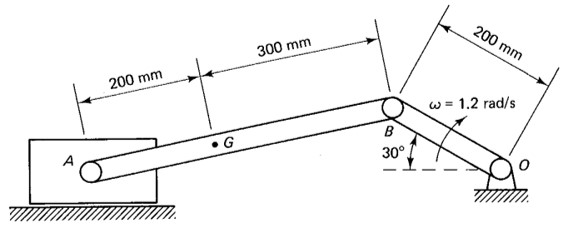

Body numbering

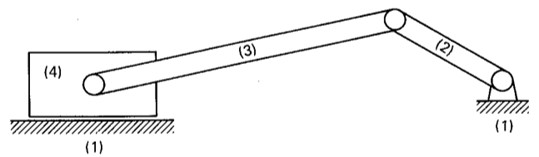

Local coordinate frames

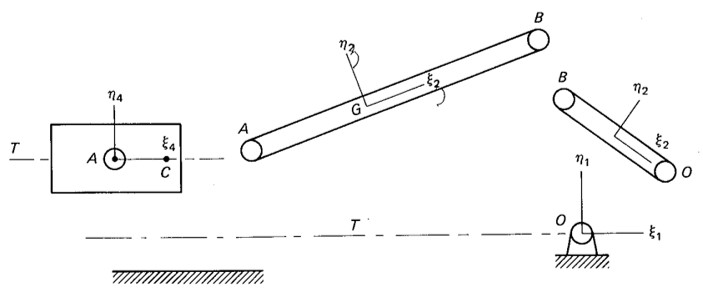

Data from the user

- Bodies and their coordinate frames.

- Joints and their characteristic points

- Solver settings

### Bodies and coordinates

close all
clear all
clc
mbs = init_mbs();
mbs = add_body(mbs, "ground");
mbs = add_body(mbs, "crank", -0.1, 0.1, -deg2rad(30));
mbs = add_body(mbs, "link", -0.45, 0.1, deg2rad(15));
mbs = add_body(mbs, "slider", -0.6)

mbs = struct with fields:
     bodies: [1×4 struct]
     joints: [1×1 struct]
         nq: 12
         nc: 0
    gravity: []
     forces: [1×1 struct]
     balpha: 5
      bbeta: 5


### Joints and characteristic points

Vectors that points to joint locations are in local coordinate frame. They do not change locations in time.

mbs = add_revolute(mbs, "revO", "ground", [0; 0], "crank", [0.1, 0.0]);
mbs = add_revolute(mbs, "revB", "crank", [-0.1; 0], "link", [0.3, 0.0]);
mbs = add_revolute(mbs, "revA", "link", [-0.2; 0], "slider", [0.0, 0.0]);

% Simple joints
mbs = add_simple_joint(mbs, "groundx", "ground", "x", 0);
mbs = add_simple_joint(mbs, "groundy", "ground", "y", 0);
mbs = add_simple_joint(mbs, "groundangle", "ground", "fi", 0);

mbs = add_simple_joint(mbs, "slidertranslation", "slider", "y", 0);
mbs = add_simple_joint(mbs, "sliderrotation", "slider", "fi", 0);

% Driving constraint for the crank
om = 1.2; % rad/s
mbs = add_driving_joint(mbs, "crankrotation", "crank", "fi", @(t)-deg2rad(30) - om * t);

### Basic checking

fprintf("System has %d bodies and %d coordinates.\n", length(mbs.bodies), mbs.nq)

System has 4 bodies and 12 coordinates.


fprintf("Number of the joints:\n\tRevolute: %d\n\tPrismatic: %d\n", ...
    length(mbs.joints.revolute), length(mbs.joints.prismatic))

Number of the joints:
	Revolute: 3
	Prismatic: 0


fprintf("\tSimple: %d\n\tDriving: %d\n", length(mbs.joints.simple), length(mbs.joints.driving))

	Simple: 5
	Driving: 1


fprintf("In total %d DOF are constrained!\n", mbs.nc)

In total 12 DOF are constrained!


### **Coordinates (initial values)**

They vere defined in the mbs.bodies. We want to put them together in single vector.

q0 = initial_position(mbs);

### Constraints vector C

t0 = 0.0;
C = constraints(mbs, q0, t0);

### Solution using fsolve

Now we can check the code with function fsolve

tic
q0_correct = fsolve(@(y)constraints(mbs, y, 0.0), q0);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


toc

Elapsed time is 0.182087 seconds.


% disp([q0, q0_correct])
C0 = constraints(mbs, q0_correct, t0)

C0 = 	1.0e+-7 *

         0
         0
    0.3009
    0.0613
    0.2006
    0.0409
         0
         0
         0
         0


### Jacobian of constraints

We need it for position and velocity analysis (and we will need it for euqations of motion).

Cq = constraints_dq(mbs, q0);

Now we can solve kinematic analysis on position (initial) using Newton-Raphson

tic
[q0_correct_NR, NR_iter] = ...
    NR_method(@(y)constraints(mbs, y, 0.0), ...
    @(y)constraints_dq(mbs, y), q0, 1e-8)

q0_correct_NR =          0
         0
         0
   -0.0866
    0.0500
   -0.5236
   -0.4671
    0.0400
    0.2014
   -0.6631


NR_iter = 3

toc

Elapsed time is 0.072292 seconds.


Simple check

disp([q0, q0_correct, q0_correct_NR])

         0         0         0
         0         0         0
         0         0         0
   -0.1000   -0.0866   -0.0866
    0.1000    0.0500    0.0500
   -0.5236   -0.5236   -0.5236
   -0.4500   -0.4671   -0.4671
    0.1000    0.0400    0.0400
    0.2618    0.2014    0.2014
   -0.6000   -0.6631   -0.6631
         0         0         0
         0         0         0



C0_NR = constraints(mbs, q0_correct_NR, t0)

C0_NR = 	1.0e+-16 *

         0
         0
    0.5551
    0.1388
         0
    0.1388
         0
         0
         0
         0


### Kinematic analysis on position

h = 0.05;
t_end = 1;
tol = 1e-8;
[T, Q, Qp, niter, QPP] = kinematic_analysis(mbs, q0, h, t_end, tol);

g =    -0.1202
    0.0793
   -0.1728
    0.0674
   -0.0351
   -0.0079
         0
         0
         0
         0


qipp =          0
    0.0000
         0
   -0.1202
    0.0793
         0
   -0.2760
    0.0635
    0.2834
   -0.2998


QPP =          0    0.0000         0   -0.1202    0.0793         0   -0.2760    0.0635    0.2834   -0.2998         0         0
         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0
         0         0      

g =    -0.1152
    0.0864
   -0.1643
    0.0742
   -0.0327
   -0.0081
         0
         0
         0
         0


qipp =          0
         0
         0
   -0.1152
    0.0864
         0
   -0.2588
    0.0691
    0.3128
   -0.2778


QPP =          0    0.0000         0   -0.1202    0.0793         0   -0.2760    0.0635    0.2834   -0.2998         0         0
         0         0         0   -0.1152    0.0864         0   -0.2588    0.0691    0.3128   -0.2778         0         0
         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0
         0         0      

g =    -0.1098
    0.0932
   -0.1551
    0.0810
   -0.0302
   -0.0081
         0
         0
         0
         0


qipp =          0
         0
         0
   -0.1098
    0.0932
         0
   -0.2403
    0.0745
    0.3421
   -0.2541


QPP =          0    0.0000         0   -0.1202    0.0793         0   -0.2760    0.0635    0.2834   -0.2998         0         0
         0         0         0   -0.1152    0.0864         0   -0.2588    0.0691    0.3128   -0.2778         0         0
         0         0         0   -0.1098    0.0932         0   -0.2403    0.0745    0.3421   -0.2541         0         0
         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0
         0         0      

g =    -0.1040
    0.0996
   -0.1454
    0.0876
   -0.0276
   -0.0080
         0
         0
         0
         0


qipp =          0
    0.0000
         0
   -0.1040
    0.0996
         0
   -0.2206
    0.0797
    0.3712
   -0.2290


QPP =          0    0.0000         0   -0.1202    0.0793         0   -0.2760    0.0635    0.2834   -0.2998         0         0
         0         0         0   -0.1152    0.0864         0   -0.2588    0.0691    0.3128   -0.2778         0         0
         0         0         0   -0.1098    0.0932         0   -0.2403    0.0745    0.3421   -0.2541         0         0
         0    0.0000         0   -0.1040    0.0996         0   -0.2206    0.0797    0.3712   -0.2290         0         0
         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0
         0         0      

g =    -0.0979
    0.1056
   -0.1352
    0.0942
   -0.0249
   -0.0077
         0
         0
         0
         0


qipp =          0
    0.0000
         0
   -0.0979
    0.1056
         0
   -0.1999
    0.0845
    0.3999
   -0.2026


QPP =          0    0.0000         0   -0.1202    0.0793         0   -0.2760    0.0635    0.2834   -0.2998         0         0
         0         0         0   -0.1152    0.0864         0   -0.2588    0.0691    0.3128   -0.2778         0         0
         0         0         0   -0.1098    0.0932         0   -0.2403    0.0745    0.3421   -0.2541         0         0
         0    0.0000         0   -0.1040    0.0996         0   -0.2206    0.0797    0.3712   -0.2290         0         0
         0    0.0000         0   -0.0979    0.1056         0   -0.1999    0.0845    0.3999   -0.2026         0         0
         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0
         0         0      

g =    -0.0913
    0.1113
   -0.1246
    0.1005
   -0.0221
   -0.0072
         0
         0
         0
         0


qipp =          0
         0
         0
   -0.0913
    0.1113
         0
   -0.1782
    0.0891
    0.4280
   -0.1753


QPP =          0    0.0000         0   -0.1202    0.0793         0   -0.2760    0.0635    0.2834   -0.2998         0         0
         0         0         0   -0.1152    0.0864         0   -0.2588    0.0691    0.3128   -0.2778         0         0
         0         0         0   -0.1098    0.0932         0   -0.2403    0.0745    0.3421   -0.2541         0         0
         0    0.0000         0   -0.1040    0.0996         0   -0.2206    0.0797    0.3712   -0.2290         0         0
         0    0.0000         0   -0.0979    0.1056         0   -0.1999    0.0845    0.3999   -0.2026         0         0
         0         0         0   -0.0913    0.1113         0   -0.1782    0.0891    0.4280   -0.1753         0         0
         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0
         0         0      

g =    -0.0845
    0.1166
   -0.1136
    0.1066
   -0.0194
   -0.0067
         0
         0
         0
         0


qipp =          0
    0.0000
         0
   -0.0845
    0.1166
         0
   -0.1559
    0.0933
    0.4554
   -0.1471


QPP =          0    0.0000         0   -0.1202    0.0793         0   -0.2760    0.0635    0.2834   -0.2998         0         0
         0         0         0   -0.1152    0.0864         0   -0.2588    0.0691    0.3128   -0.2778         0         0
         0         0         0   -0.1098    0.0932         0   -0.2403    0.0745    0.3421   -0.2541         0         0
         0    0.0000         0   -0.1040    0.0996         0   -0.2206    0.0797    0.3712   -0.2290         0         0
         0    0.0000         0   -0.0979    0.1056         0   -0.1999    0.0845    0.3999   -0.2026         0         0
         0         0         0   -0.0913    0.1113         0   -0.1782    0.0891    0.4280   -0.1753         0         0
         0    0.0000         0   -0.0845    0.1166         0   -0.1559    0.0933    0.4554   -0.1471         0         0
         0         0         0         0         0         0         0         0         0         0         0         0
         0         0      

g =    -0.0774
    0.1215
   -0.1024
    0.1125
   -0.0167
   -0.0060
         0
         0
         0
         0


qipp =          0
         0
         0
   -0.0774
    0.1215
         0
   -0.1330
    0.0972
    0.4818
   -0.1184


QPP =          0    0.0000         0   -0.1202    0.0793         0   -0.2760    0.0635    0.2834   -0.2998         0         0
         0         0         0   -0.1152    0.0864         0   -0.2588    0.0691    0.3128   -0.2778         0         0
         0         0         0   -0.1098    0.0932         0   -0.2403    0.0745    0.3421   -0.2541         0         0
         0    0.0000         0   -0.1040    0.0996         0   -0.2206    0.0797    0.3712   -0.2290         0         0
         0    0.0000         0   -0.0979    0.1056         0   -0.1999    0.0845    0.3999   -0.2026         0         0
         0         0         0   -0.0913    0.1113         0   -0.1782    0.0891    0.4280   -0.1753         0         0
         0    0.0000         0   -0.0845    0.1166         0   -0.1559    0.0933    0.4554   -0.1471         0         0
         0         0         0   -0.0774    0.1215         0   -0.1330    0.0972    0.4818   -0.1184         0         0
         0         0      

g =    -0.0699
    0.1259
   -0.0910
    0.1180
   -0.0141
   -0.0053
         0
         0
         0
         0


qipp =          0
         0
         0
   -0.0699
    0.1259
         0
   -0.1097
    0.1007
    0.5069
   -0.0895


QPP =          0    0.0000         0   -0.1202    0.0793         0   -0.2760    0.0635    0.2834   -0.2998         0         0
         0         0         0   -0.1152    0.0864         0   -0.2588    0.0691    0.3128   -0.2778         0         0
         0         0         0   -0.1098    0.0932         0   -0.2403    0.0745    0.3421   -0.2541         0         0
         0    0.0000         0   -0.1040    0.0996         0   -0.2206    0.0797    0.3712   -0.2290         0         0
         0    0.0000         0   -0.0979    0.1056         0   -0.1999    0.0845    0.3999   -0.2026         0         0
         0         0         0   -0.0913    0.1113         0   -0.1782    0.0891    0.4280   -0.1753         0         0
         0    0.0000         0   -0.0845    0.1166         0   -0.1559    0.0933    0.4554   -0.1471         0         0
         0         0         0   -0.0774    0.1215         0   -0.1330    0.0972    0.4818   -0.1184         0         0
         0         0      

g =    -0.0623
    0.1298
   -0.0796
    0.1231
   -0.0115
   -0.0045
         0
         0
         0
         0


qipp =          0
         0
         0
   -0.0623
    0.1298
         0
   -0.0862
    0.1039
    0.5305
   -0.0607


QPP =          0    0.0000         0   -0.1202    0.0793         0   -0.2760    0.0635    0.2834   -0.2998         0         0
         0         0         0   -0.1152    0.0864         0   -0.2588    0.0691    0.3128   -0.2778         0         0
         0         0         0   -0.1098    0.0932         0   -0.2403    0.0745    0.3421   -0.2541         0         0
         0    0.0000         0   -0.1040    0.0996         0   -0.2206    0.0797    0.3712   -0.2290         0         0
         0    0.0000         0   -0.0979    0.1056         0   -0.1999    0.0845    0.3999   -0.2026         0         0
         0         0         0   -0.0913    0.1113         0   -0.1782    0.0891    0.4280   -0.1753         0         0
         0    0.0000         0   -0.0845    0.1166         0   -0.1559    0.0933    0.4554   -0.1471         0         0
         0         0         0   -0.0774    0.1215         0   -0.1330    0.0972    0.4818   -0.1184         0         0
         0         0      

g =    -0.0544
    0.1333
   -0.0682
    0.1278
   -0.0092
   -0.0037
         0
         0
         0
         0


qipp =          0
         0
         0
   -0.0544
    0.1333
         0
   -0.0628
    0.1067
    0.5521
   -0.0322


QPP =          0    0.0000         0   -0.1202    0.0793         0   -0.2760    0.0635    0.2834   -0.2998         0         0
         0         0         0   -0.1152    0.0864         0   -0.2588    0.0691    0.3128   -0.2778         0         0
         0         0         0   -0.1098    0.0932         0   -0.2403    0.0745    0.3421   -0.2541         0         0
         0    0.0000         0   -0.1040    0.0996         0   -0.2206    0.0797    0.3712   -0.2290         0         0
         0    0.0000         0   -0.0979    0.1056         0   -0.1999    0.0845    0.3999   -0.2026         0         0
         0         0         0   -0.0913    0.1113         0   -0.1782    0.0891    0.4280   -0.1753         0         0
         0    0.0000         0   -0.0845    0.1166         0   -0.1559    0.0933    0.4554   -0.1471         0         0
         0         0         0   -0.0774    0.1215         0   -0.1330    0.0972    0.4818   -0.1184         0         0
         0         0      

g =    -0.0463
    0.1364
   -0.0568
    0.1320
   -0.0070
   -0.0029
         0
         0
         0
         0


qipp =          0
         0
         0
   -0.0463
    0.1364
         0
   -0.0396
    0.1091
    0.5717
   -0.0043


QPP =          0    0.0000         0   -0.1202    0.0793         0   -0.2760    0.0635    0.2834   -0.2998         0         0
         0         0         0   -0.1152    0.0864         0   -0.2588    0.0691    0.3128   -0.2778         0         0
         0         0         0   -0.1098    0.0932         0   -0.2403    0.0745    0.3421   -0.2541         0         0
         0    0.0000         0   -0.1040    0.0996         0   -0.2206    0.0797    0.3712   -0.2290         0         0
         0    0.0000         0   -0.0979    0.1056         0   -0.1999    0.0845    0.3999   -0.2026         0         0
         0         0         0   -0.0913    0.1113         0   -0.1782    0.0891    0.4280   -0.1753         0         0
         0    0.0000         0   -0.0845    0.1166         0   -0.1559    0.0933    0.4554   -0.1471         0         0
         0         0         0   -0.0774    0.1215         0   -0.1330    0.0972    0.4818   -0.1184         0         0
         0         0      

g =    -0.0380
    0.1389
   -0.0457
    0.1357
   -0.0051
   -0.0021
         0
         0
         0
         0


qipp =          0
    0.0000
         0
   -0.0380
    0.1389
         0
   -0.0168
    0.1111
    0.5887
    0.0226


QPP =          0    0.0000         0   -0.1202    0.0793         0   -0.2760    0.0635    0.2834   -0.2998         0         0
         0         0         0   -0.1152    0.0864         0   -0.2588    0.0691    0.3128   -0.2778         0         0
         0         0         0   -0.1098    0.0932         0   -0.2403    0.0745    0.3421   -0.2541         0         0
         0    0.0000         0   -0.1040    0.0996         0   -0.2206    0.0797    0.3712   -0.2290         0         0
         0    0.0000         0   -0.0979    0.1056         0   -0.1999    0.0845    0.3999   -0.2026         0         0
         0         0         0   -0.0913    0.1113         0   -0.1782    0.0891    0.4280   -0.1753         0         0
         0    0.0000         0   -0.0845    0.1166         0   -0.1559    0.0933    0.4554   -0.1471         0         0
         0         0         0   -0.0774    0.1215         0   -0.1330    0.0972    0.4818   -0.1184         0         0
         0         0      

g =    -0.0296
    0.1409
   -0.0348
    0.1387
   -0.0035
   -0.0015
         0
         0
         0
         0


qipp =          0
   -0.0000
         0
   -0.0296
    0.1409
         0
    0.0053
    0.1127
    0.6030
    0.0484


QPP =          0    0.0000         0   -0.1202    0.0793         0   -0.2760    0.0635    0.2834   -0.2998         0         0
         0         0         0   -0.1152    0.0864         0   -0.2588    0.0691    0.3128   -0.2778         0         0
         0         0         0   -0.1098    0.0932         0   -0.2403    0.0745    0.3421   -0.2541         0         0
         0    0.0000         0   -0.1040    0.0996         0   -0.2206    0.0797    0.3712   -0.2290         0         0
         0    0.0000         0   -0.0979    0.1056         0   -0.1999    0.0845    0.3999   -0.2026         0         0
         0         0         0   -0.0913    0.1113         0   -0.1782    0.0891    0.4280   -0.1753         0         0
         0    0.0000         0   -0.0845    0.1166         0   -0.1559    0.0933    0.4554   -0.1471         0         0
         0         0         0   -0.0774    0.1215         0   -0.1330    0.0972    0.4818   -0.1184         0         0
         0         0      

g =    -0.0211
    0.1424
   -0.0243
    0.1411
   -0.0021
   -0.0009
         0
         0
         0
         0


qipp =          0
         0
         0
   -0.0211
    0.1424
         0
    0.0267
    0.1140
    0.6142
    0.0727


QPP =          0    0.0000         0   -0.1202    0.0793         0   -0.2760    0.0635    0.2834   -0.2998         0         0
         0         0         0   -0.1152    0.0864         0   -0.2588    0.0691    0.3128   -0.2778         0         0
         0         0         0   -0.1098    0.0932         0   -0.2403    0.0745    0.3421   -0.2541         0         0
         0    0.0000         0   -0.1040    0.0996         0   -0.2206    0.0797    0.3712   -0.2290         0         0
         0    0.0000         0   -0.0979    0.1056         0   -0.1999    0.0845    0.3999   -0.2026         0         0
         0         0         0   -0.0913    0.1113         0   -0.1782    0.0891    0.4280   -0.1753         0         0
         0    0.0000         0   -0.0845    0.1166         0   -0.1559    0.0933    0.4554   -0.1471         0         0
         0         0         0   -0.0774    0.1215         0   -0.1330    0.0972    0.4818   -0.1184         0         0
         0         0      

g =    -0.0125
    0.1435
   -0.0142
    0.1427
   -0.0011
   -0.0005
         0
         0
         0
         0


qipp =          0
    0.0000
         0
   -0.0125
    0.1435
         0
    0.0472
    0.1148
    0.6222
    0.0953


QPP = 21×12
         0    0.0000         0   -0.1202    0.0793         0   -0.2760    0.0635    0.2834   -0.2998         0         0
         0         0         0   -0.1152    0.0864         0   -0.2588    0.0691    0.3128   -0.2778         0         0
         0         0         0   -0.1098    0.0932         0   -0.2403    0.0745    0.3421   -0.2541         0         0
         0    0.0000         0   -0.1040    0.0996         0   -0.2206    0.0797    0.3712   -0.2290         0         0
         0    0.0000         0   -0.0979    0.1056         0   -0.1999    0.0845    0.3999   -0.2026         0         0
         0         0         0   -0.0913    0.1113         0   -0.1782    0.0891    0.4280   -0.1753         0         0
         0    0.0000         0   -0.0845    0.1166         0   -0.1559    0.0933    0.4554   -0.1471         0         0
         0         0         0   -0.0774    0.1215         0   -0.1330    0.0972    0.4818   -0.1184         0         0
         0         0

g = 12×1
   -0.0039
    0.1439
   -0.0045
    0.1437
   -0.0004
   -0.0002
         0
         0
         0
         0


qipp = 12×1
         0
         0
         0
   -0.0039
    0.1439
         0
    0.0665
    0.1152
    0.6269
    0.1161


QPP = 21×12
         0    0.0000         0   -0.1202    0.0793         0   -0.2760    0.0635    0.2834   -0.2998         0         0
         0         0         0   -0.1152    0.0864         0   -0.2588    0.0691    0.3128   -0.2778         0         0
         0         0         0   -0.1098    0.0932         0   -0.2403    0.0745    0.3421   -0.2541         0         0
         0    0.0000         0   -0.1040    0.0996         0   -0.2206    0.0797    0.3712   -0.2290         0         0
         0    0.0000         0   -0.0979    0.1056         0   -0.1999    0.0845    0.3999   -0.2026         0         0
         0         0         0   -0.0913    0.1113         0   -0.1782    0.0891    0.4280   -0.1753         0         0
         0    0.0000         0   -0.0845    0.1166         0   -0.1559    0.0933    0.4554   -0.1471         0         0
         0         0         0   -0.0774    0.1215         0   -0.1330    0.0972    0.4818   -0.1184         0         0
         0         0

g = 12×1
    0.0047
    0.1439
    0.0047
    0.1439
   -0.0000
   -0.0000
         0
         0
         0
         0


qipp = 12×1
         0
         0
         0
    0.0047
    0.1439
         0
    0.0847
    0.1151
    0.6280
    0.1349


QPP = 21×12
         0    0.0000         0   -0.1202    0.0793         0   -0.2760    0.0635    0.2834   -0.2998         0         0
         0         0         0   -0.1152    0.0864         0   -0.2588    0.0691    0.3128   -0.2778         0         0
         0         0         0   -0.1098    0.0932         0   -0.2403    0.0745    0.3421   -0.2541         0         0
         0    0.0000         0   -0.1040    0.0996         0   -0.2206    0.0797    0.3712   -0.2290         0         0
         0    0.0000         0   -0.0979    0.1056         0   -0.1999    0.0845    0.3999   -0.2026         0         0
         0         0         0   -0.0913    0.1113         0   -0.1782    0.0891    0.4280   -0.1753         0         0
         0    0.0000         0   -0.0845    0.1166         0   -0.1559    0.0933    0.4554   -0.1471         0         0
         0         0         0   -0.0774    0.1215         0   -0.1330    0.0972    0.4818   -0.1184         0         0
         0         0

g = 12×1
    0.0133
    0.1434
    0.0133
    0.1433
   -0.0001
   -0.0000
         0
         0
         0
         0


qipp = 12×1
         0
         0
         0
    0.0133
    0.1434
         0
    0.1016
    0.1147
    0.6256
    0.1516


QPP = 21×12
         0    0.0000         0   -0.1202    0.0793         0   -0.2760    0.0635    0.2834   -0.2998         0         0
         0         0         0   -0.1152    0.0864         0   -0.2588    0.0691    0.3128   -0.2778         0         0
         0         0         0   -0.1098    0.0932         0   -0.2403    0.0745    0.3421   -0.2541         0         0
         0    0.0000         0   -0.1040    0.0996         0   -0.2206    0.0797    0.3712   -0.2290         0         0
         0    0.0000         0   -0.0979    0.1056         0   -0.1999    0.0845    0.3999   -0.2026         0         0
         0         0         0   -0.0913    0.1113         0   -0.1782    0.0891    0.4280   -0.1753         0         0
         0    0.0000         0   -0.0845    0.1166         0   -0.1559    0.0933    0.4554   -0.1471         0         0
         0         0         0   -0.0774    0.1215         0   -0.1330    0.0972    0.4818   -0.1184         0         0
         0         0

g = 12×1
    0.0219
    0.1423
    0.0213
    0.1420
   -0.0004
   -0.0002
         0
         0
         0
         0


qipp = 12×1
         0
         0
         0
    0.0219
    0.1423
         0
    0.1172
    0.1139
    0.6196
    0.1661


QPP = 21×12
         0    0.0000         0   -0.1202    0.0793         0   -0.2760    0.0635    0.2834   -0.2998         0         0
         0         0         0   -0.1152    0.0864         0   -0.2588    0.0691    0.3128   -0.2778         0         0
         0         0         0   -0.1098    0.0932         0   -0.2403    0.0745    0.3421   -0.2541         0         0
         0    0.0000         0   -0.1040    0.0996         0   -0.2206    0.0797    0.3712   -0.2290         0         0
         0    0.0000         0   -0.0979    0.1056         0   -0.1999    0.0845    0.3999   -0.2026         0         0
         0         0         0   -0.0913    0.1113         0   -0.1782    0.0891    0.4280   -0.1753         0         0
         0    0.0000         0   -0.0845    0.1166         0   -0.1559    0.0933    0.4554   -0.1471         0         0
         0         0         0   -0.0774    0.1215         0   -0.1330    0.0972    0.4818   -0.1184         0         0
         0         0

g = 12×1
    0.0304
    0.1408
    0.0287
    0.1400
   -0.0012
   -0.0005
         0
         0
         0
         0


qipp = 12×1
         0
         0
         0
    0.0304
    0.1408
         0
    0.1315
    0.1126
    0.6102
    0.1785


QPP = 21×12
         0    0.0000         0   -0.1202    0.0793         0   -0.2760    0.0635    0.2834   -0.2998         0         0
         0         0         0   -0.1152    0.0864         0   -0.2588    0.0691    0.3128   -0.2778         0         0
         0         0         0   -0.1098    0.0932         0   -0.2403    0.0745    0.3421   -0.2541         0         0
         0    0.0000         0   -0.1040    0.0996         0   -0.2206    0.0797    0.3712   -0.2290         0         0
         0    0.0000         0   -0.0979    0.1056         0   -0.1999    0.0845    0.3999   -0.2026         0         0
         0         0         0   -0.0913    0.1113         0   -0.1782    0.0891    0.4280   -0.1753         0         0
         0    0.0000         0   -0.0845    0.1166         0   -0.1559    0.0933    0.4554   -0.1471         0         0
         0         0         0   -0.0774    0.1215         0   -0.1330    0.0972    0.4818   -0.1184         0         0
         0         0

Very basic postprocessing

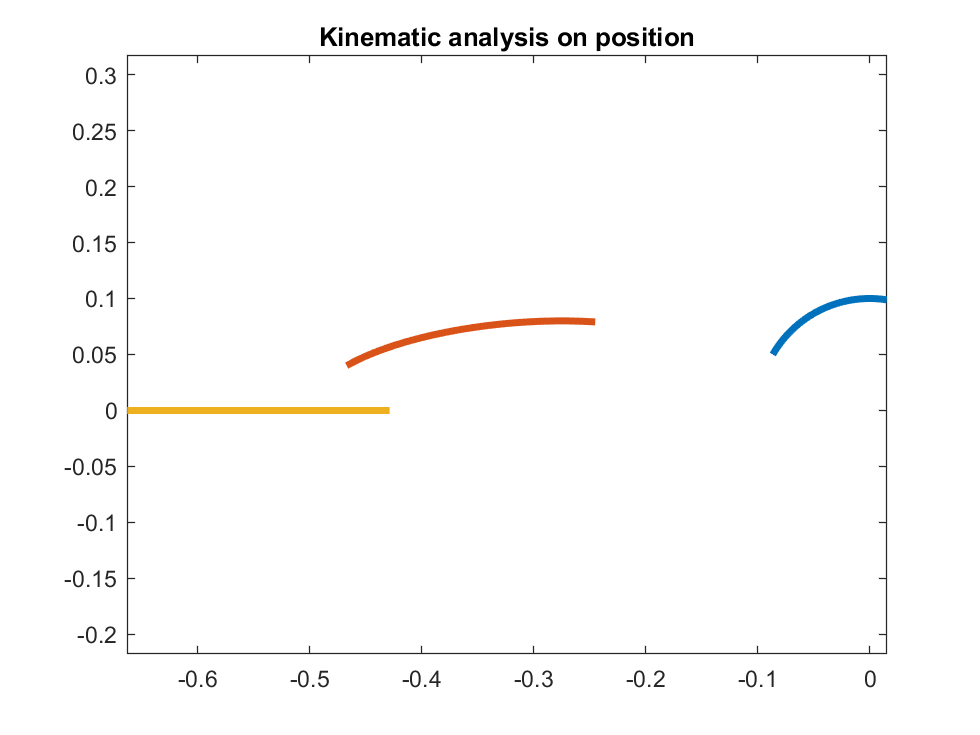

plot(Q(:, 4), Q(:, 5), Q(:, 7), Q(:, 8), ...
    Q(:, 10), Q(:, 11), 'LineWidth', 3)
axis equal
title('Kinematic analysis on position')

Now similar plot for velocity

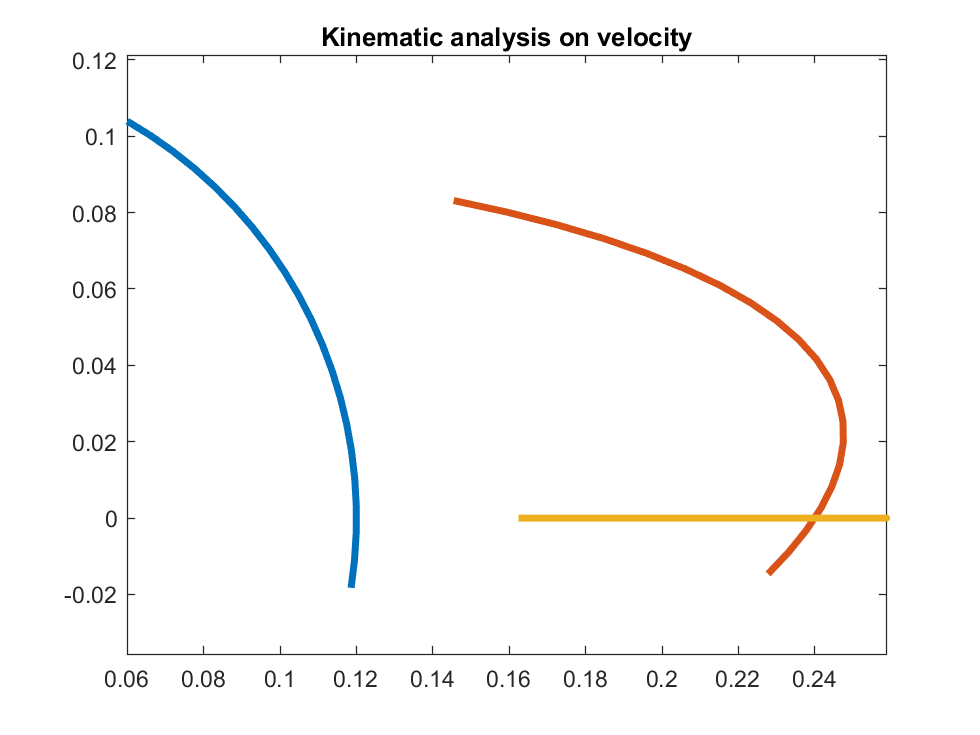

plot(Qp(:, 4), Qp(:, 5), Qp(:, 7), Qp(:, 8), ...
    Qp(:, 10), Qp(:, 11), 'LineWidth', 3)
axis equal
title('Kinematic analysis on velocity')

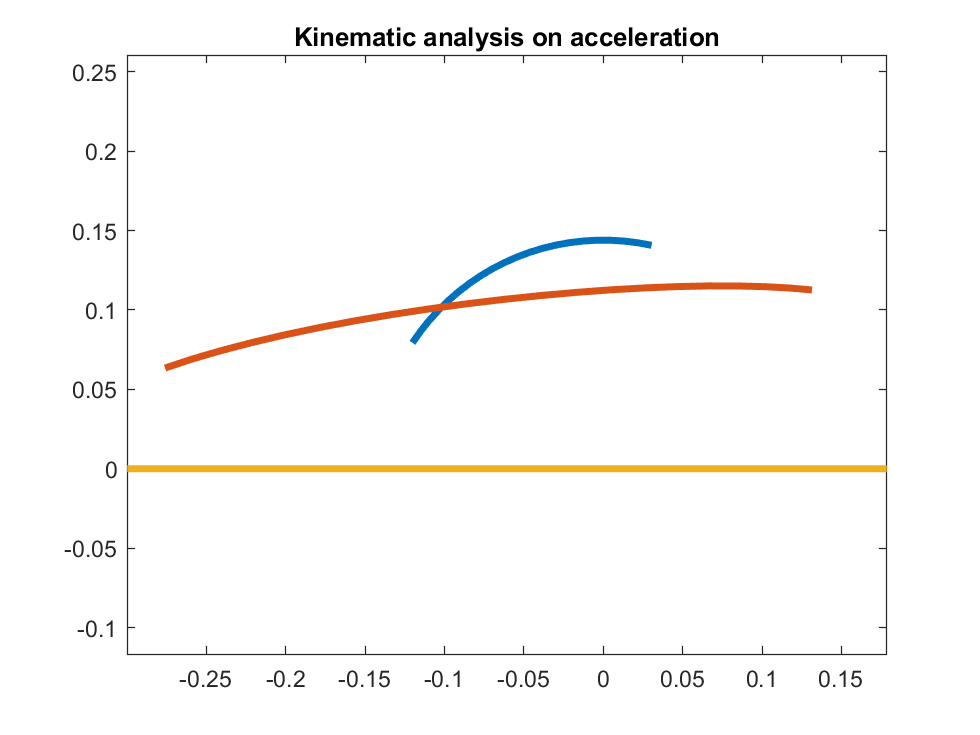

plot(QPP(:, 4), QPP(:, 5), QPP(:, 7), QPP(:, 8), ...
    QPP(:, 10), QPP(:, 11), 'LineWidth', 3)
axis equal
title('Kinematic analysis on acceleration')

Number of NR iterations

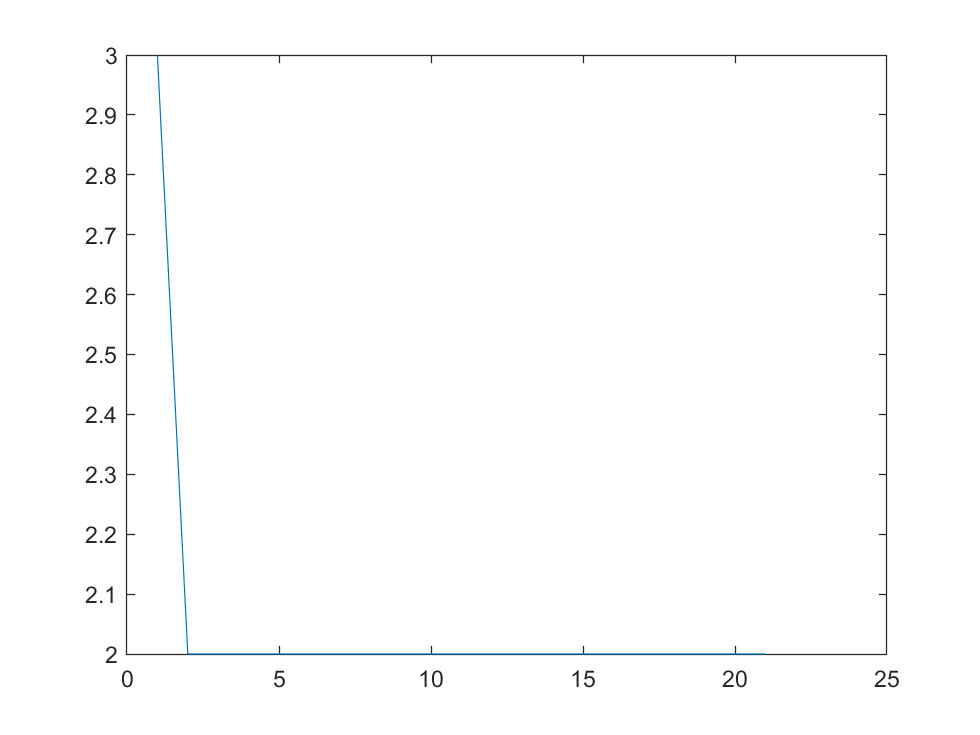

plot(niter)